## Dynamical analysis

We plan to extend the definition provided for kinematic analysis for data required by dynamical analysis (inertias and forces).

Next we will form equations of motion for the system of unconstrained bodies.

Finally we will solve the general multibody equations of motion.

### Bodies, inertias, and coordinates

mbs = init_mbs();
% mbs = add_body(mbs, "ground");
mbs = add_body(mbs, "crank", -0.1, 0.1, -deg2rad(30), 'm', 2.0, 'Ic', 2.0 * 0.2^2 / 12);
mbs = add_body(mbs, "link", -0.45, 0.1, deg2rad(15), 'm', 1.0, 'Ic', 0.5^2 / 12);
mbs = add_body(mbs, "slider", -0.6, 'm', 3.0, 'Ic', 0.1)

mbs = struct with fields:
     bodies: [1×3 struct]
     joints: [1×1 struct]
         nq: 9
         nc: 0
    gravity: []
     forces: [1×1 struct]
     balpha: 5
      bbeta: 5


mbs = add_body(mbs, "car", -0.7, 'm', 50.0, 'Ic', 0.5)

mbs = struct with fields:
     bodies: [1×4 struct]
     joints: [1×1 struct]
         nq: 12
         nc: 0
    gravity: []
     forces: [1×1 struct]
     balpha: 5
      bbeta: 5



mbs = add_revolute(mbs, "revB", "crank", [-0.1; 0], "link", [0.3, 0.0]);
mbs = add_revolute(mbs, "revA", "link", [-0.2; 0], "slider", [0.0, 0.0]);

% Translational joints
mbs = add_translational(mbs, "transPiston", "car", [-0.2; 0.0], "slider", [0.2, 0.0]);

% mbs = add_simple_joint(mbs, "slidertranslation", "slider", "y", 0);
mbs = add_simple_joint(mbs, "sliderrotation", "slider", "fi", 0);

% Driving constraint for the crank
om = 1.2; % rad/s
mbs = add_driving_joint(mbs, "crankrotation", "crank", "fi", @(t)-deg2rad(30) - om * t);


Get mass matrix

M = mass_matrix(mbs)

M =     2.0000         0         0         0         0         0         0         0         0         0         0         0
         0    2.0000         0         0         0         0         0         0         0         0         0         0
         0         0    0.0067         0         0         0         0         0         0         0         0         0
         0         0         0    1.0000         0         0         0         0         0         0         0         0
         0         0         0         0    1.0000         0         0         0         0         0         0         0
         0         0         0         0         0    0.0208         0         0         0         0         0         0
         0         0         0         0         0         0    3.0000         0         0         0         0         0
         0         0         0         0         0         0         0    3.0000         0         0         0         0
         0         0        

### Forces definition

mbs = add_gravity(mbs, [0, -9.81]);
mbs = add_point_force(mbs,"carforce","car",[0,-100])

mbs = struct with fields:
     bodies: [1×4 struct]
     joints: [1×1 struct]
         nq: 12
         nc: 8
    gravity: [2×1 double]
     forces: [1×1 struct]
     balpha: 5
      bbeta: 5


### Force vector

q0 = initial_position(mbs);
F = forces(mbs, q0)

F =          0
  -19.6200
         0
         0
 -109.8100
         0
         0
  -29.4300
         0
         0


Simple checking for the gravity forces

qpp = M\F

qpp =          0
   -9.8100
         0
         0
 -109.8100
         0
         0
   -9.8100
         0
         0


### Solve system using EulerCromer

Define all the inputs to the system

% [t, U, V] = EulerCromer(accfun, T, U_0, V_0, dt)

T = 1.0;
qd0 = zeros(size(q0)); % initial velocity
qd0([1, 5]) = -0.1; % Set vx of crank and vy of link
h = 0.01;
accfun = @(t, q)acceleration(mbs, q, t, h);
[t, Q, Qp] = eqn_of_motion(accfun, T, q0, qd0, h);

Make some plots to check the results

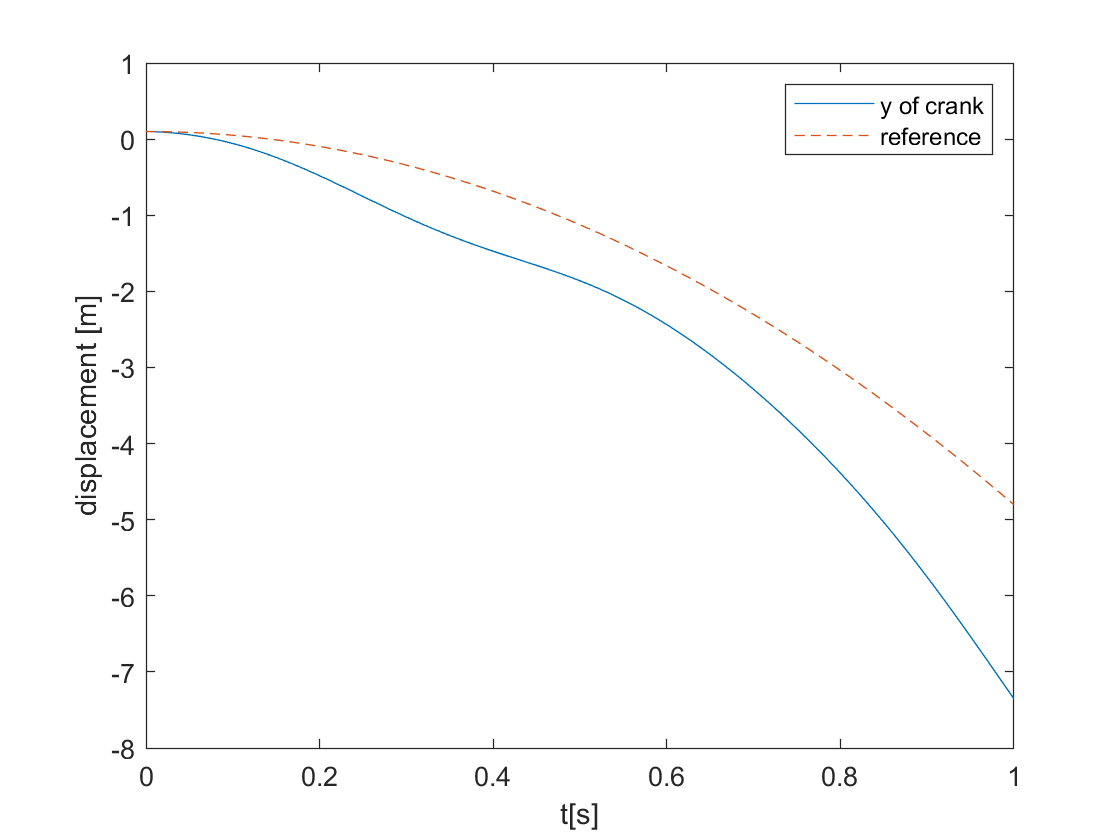

plot(t, Q(:, 2), t, q0(2) + t.*qd0(2) - 9.81 * 0.5 .* t .^ 2, '--')
legend('y of crank', 'reference')
xlabel('t[s]')
ylabel('displacement [m]')

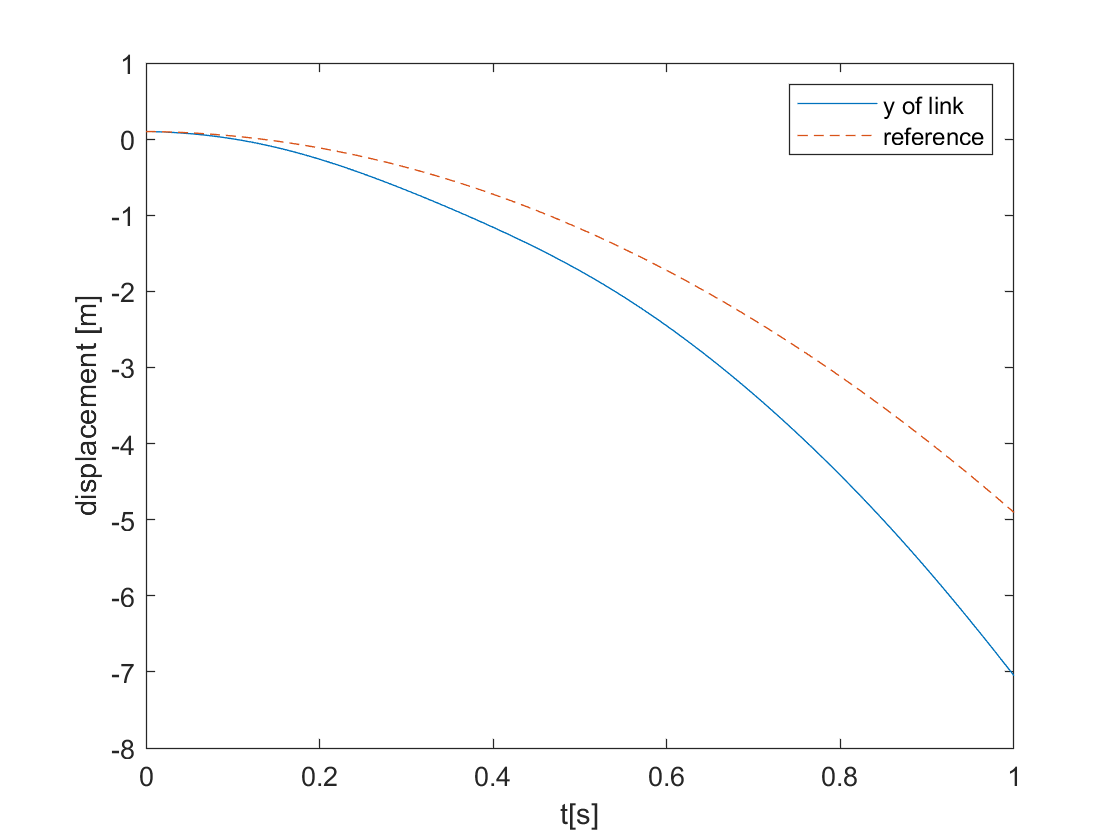

plot(t, Q(:, 5), t, q0(5) + t.*qd0(5) - 9.81 * 0.5 .* t .^ 2, '--')
legend('y of link', 'reference')
xlabel('t[s]')
ylabel('displacement [m]')